## Software Engineering/Mechatronics 3DX4

DAY CLASS

DURATION OF EXAMINATION: 2.5 Hours

McMaster University Final Examination

Dr. Mark Lawford

April 2020

Special Instructions:

This is an open book exam. You may use your course notes, any material from Avenue or on the web. You may not post these questions to web forms and solicit help from other students in the class or any other individuals. Any online discussion of the exam questions should take place in the McMaster MECTHRON/SFWRENG 3DX4 Microsoft Teams Exam Channel.  

By submitting this work, I certify that the work represents solely my own independent efforts. I confirm that I am expected to exhibit honesty and use ethical behaviour in all aspects of the learning process.  I confirm that it is my responsibility to understand what constitutes academic dishonesty under the Academic Integrity Policy.

Link:  https://secretariat.mcmaster.ca/app/uploads/Academic-Integrity-Policy-1-1.pdf

clear
% uncomment and enter your name and student number as strings 
% in the variables below
% name="Lastname, Firstname"
% studentNumber="YourStudent#"

**1. Time Response** (20 marks)

a) (5 marks) You have collected some data in the lab for an electric motor. In response to a 1V unit step input, the output rotational velocity of the motor in rad/s was recorded and stored in a data file which we will not load and plot: 

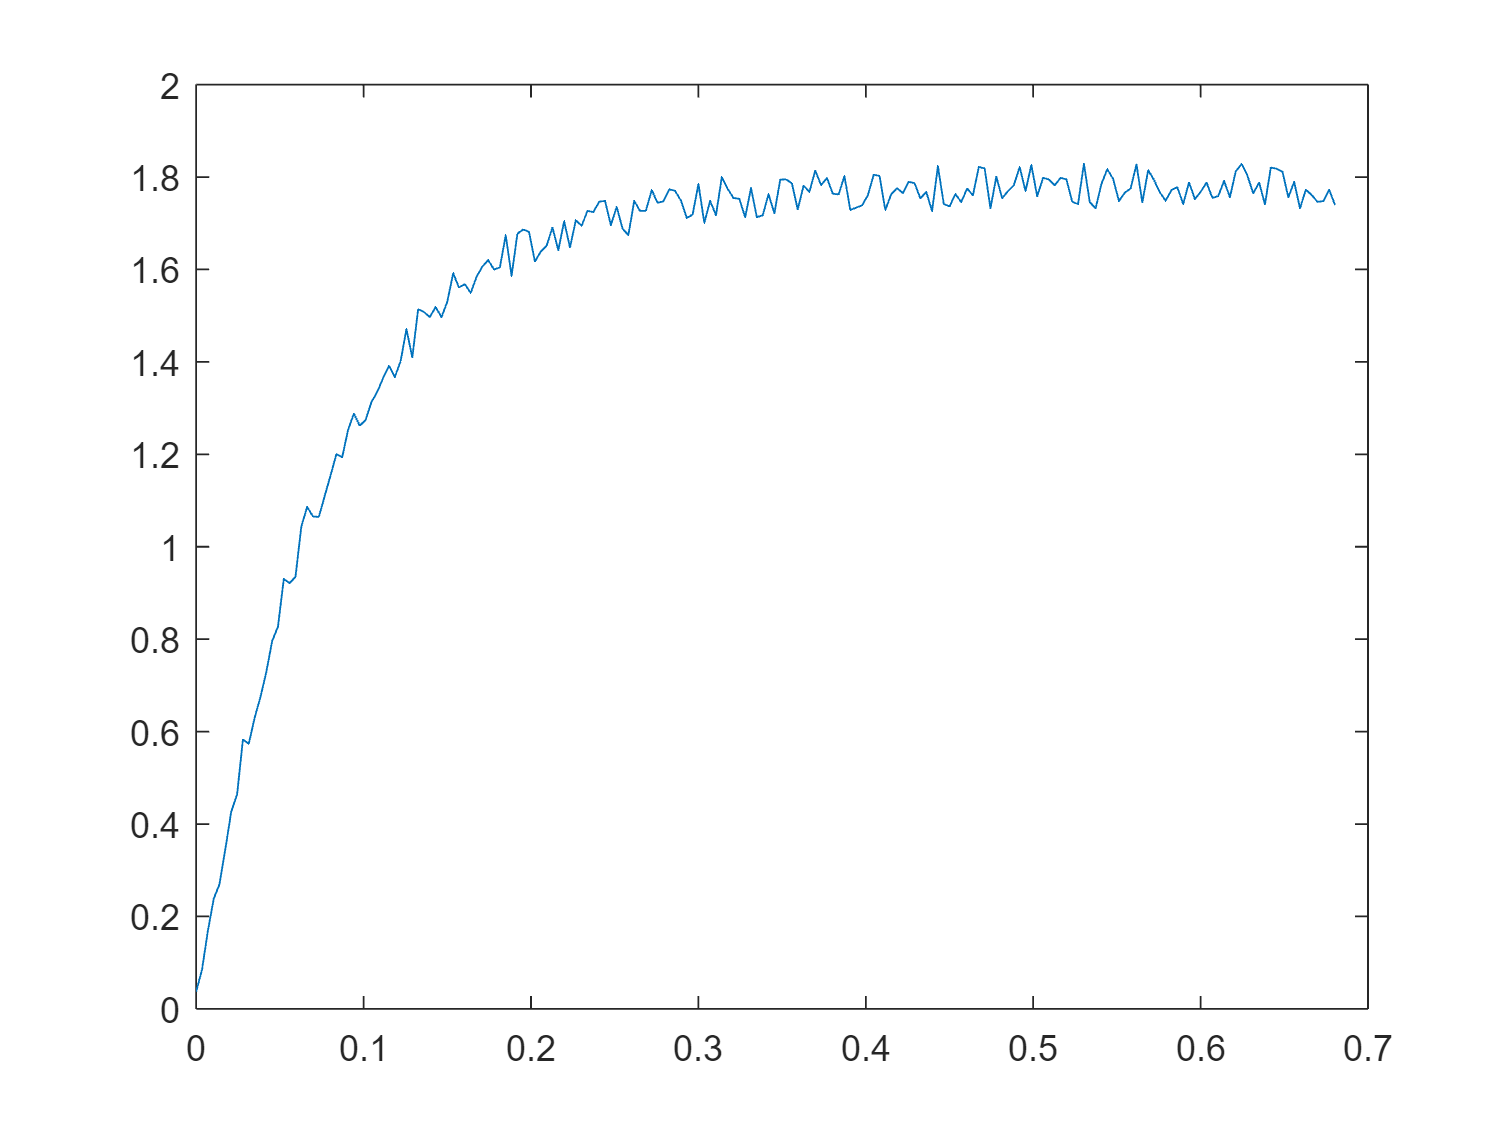

load("labdataFinal20.mat")
plot(t,omega_measured)

You have to determine the approximate transfer function of the motor to match the data. Clever bunny that you are, you know that a good approximate linear model in this case is $G(s)=\frac{K_m}{s+\alpha}$. By any means create a model that fits the data reasonably well and then plot step response of you model against the data to visually compare your fitted model with the data.

omega_ss = mean(omega_measured(length(omega_measured)-20:length(omega_measured)));
[m,i] = min(abs(omega_measured-omega_ss*(1-exp(-1))));
tau = t(i);
alpha = 1/tau;
K_m = alpha*omega_ss;
G_omega= tf([0 K_m],[1 alpha])  %Assign your model to this variable

G_omega =
 
    23.15
  ---------
  s + 13.03
 
Continuous-time transfer function.



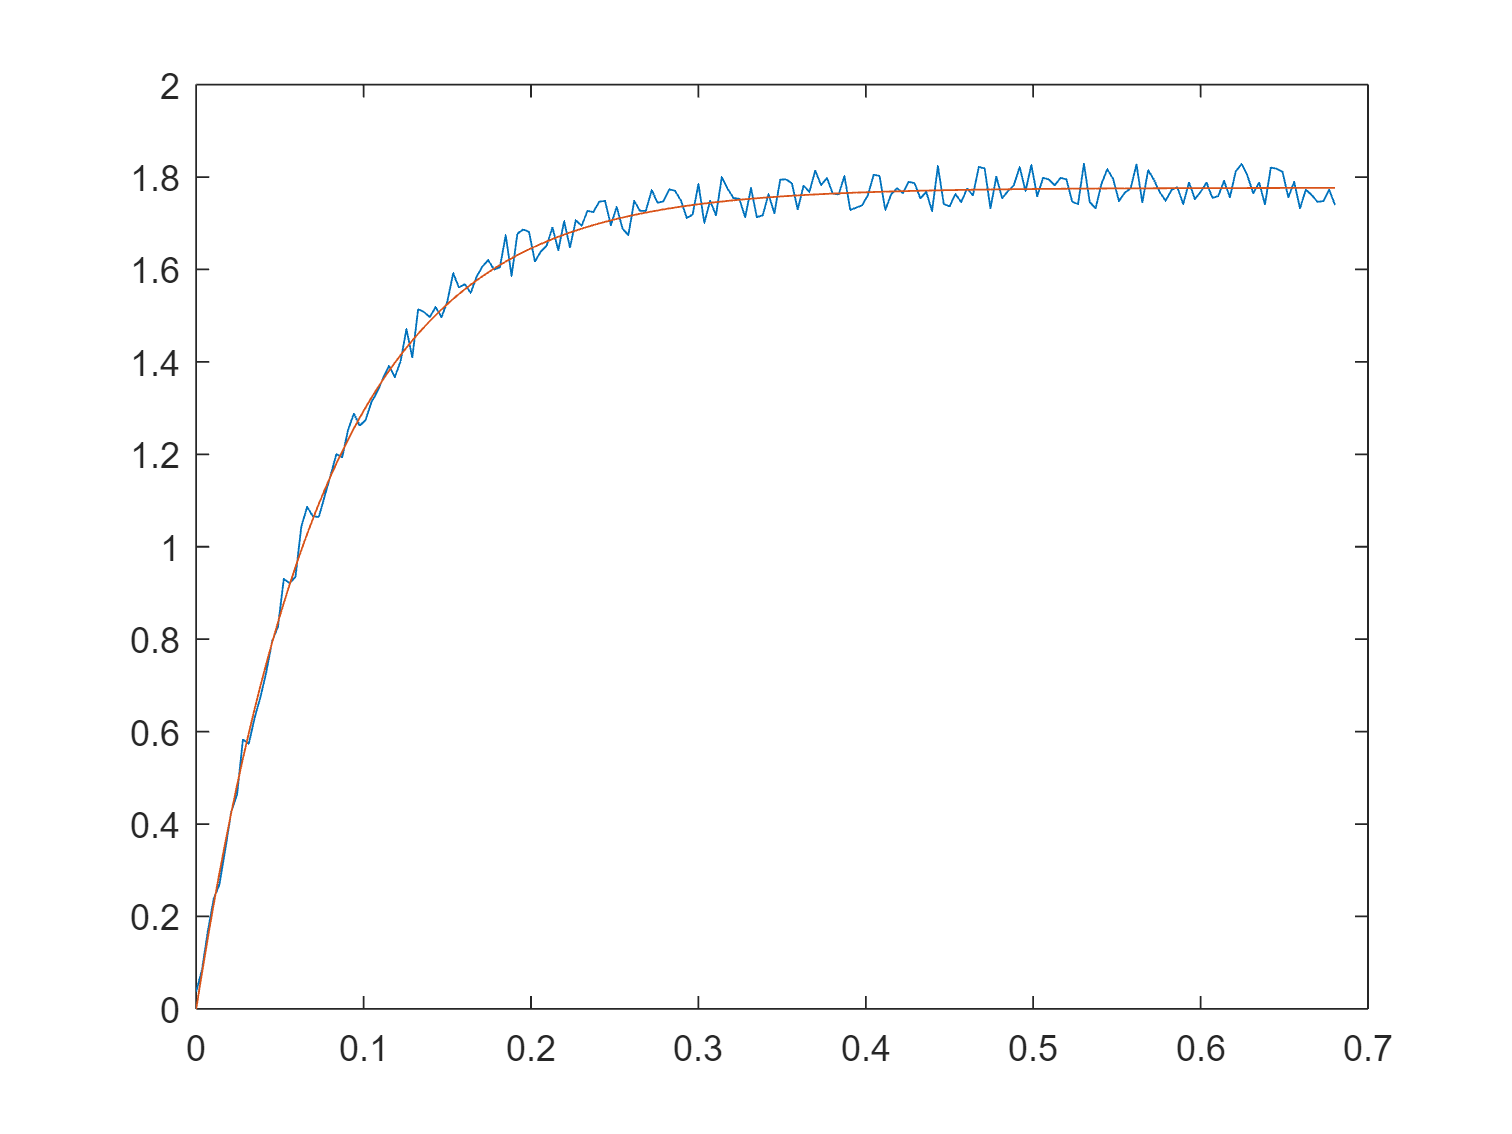

%uncomment the commands below to plot the step response of your model and compare it
%to the data
omega_guess=step(G_omega,t);
plot(t,omega_measured,t,omega_guess)

b) (5 marks) Consider the 2nd order system:


$$G(s)=\frac{30}{s^2+4s+20}$$


What is the damping ratio and natural frequency of this system?

- We know 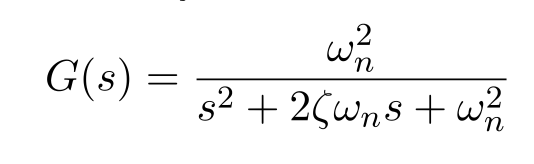

omega_nQ1b= sqrt(20)

omega_nQ1b = 4.4721

zeta_Q1b= 4/(2*omega_nQ1b)

zeta_Q1b = 0.4472

Is the system overdamped, critically damped or underdamped?

% Uncomment the correct answer
%Q1bSystemIsOverDamped=true
%Q1bSystemIsCriticallyDamped=true

Q1bSystemIsUnderDamped=true     % since 0 < zeta < 1

Q1bSystemIsUnderDamped = logical
   1


c) (5 marks) What is the expect settling time and % overshoot of the system $G(s)=\frac{30}{s^2+4s+20}$ in response to a step input?

- Settling Time:

-  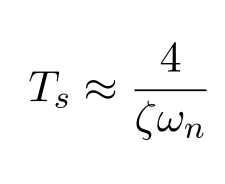

- %OS:

-  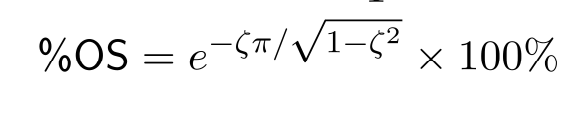

% You code goes here

T_sQ1c= 4/(zeta_Q1b*omega_nQ1b)

T_sQ1c = 2

pos_Q1c= exp((-zeta_Q1b*pi)/sqrt(1-zeta_Q1b^2))

pos_Q1c = 0.2079

d) (5 marks) Suppose we use $D(s) = K$ in and $G(s) = \frac{30}{s^2 +4s+20}$ in the control system:

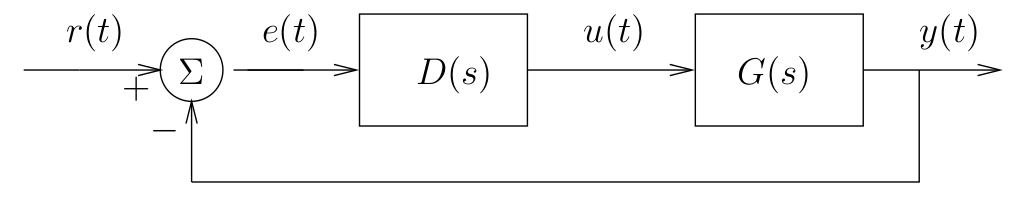

 Sketch the root locus for $K > 0$.

% You code goes here

syms s 

K = 2;
D_s = K;
G_s = 30/(s^2+4*s+20);
T_s = (D_s*G_s)/(1+D_s*G_s);
T_s = collect(T_s);
T_s_tf = tf([0 0 30*K], [1 4 30*K+20])

T_s_tf =
 
        60
  --------------
  s^2 + 4 s + 80
 
Continuous-time transfer function.



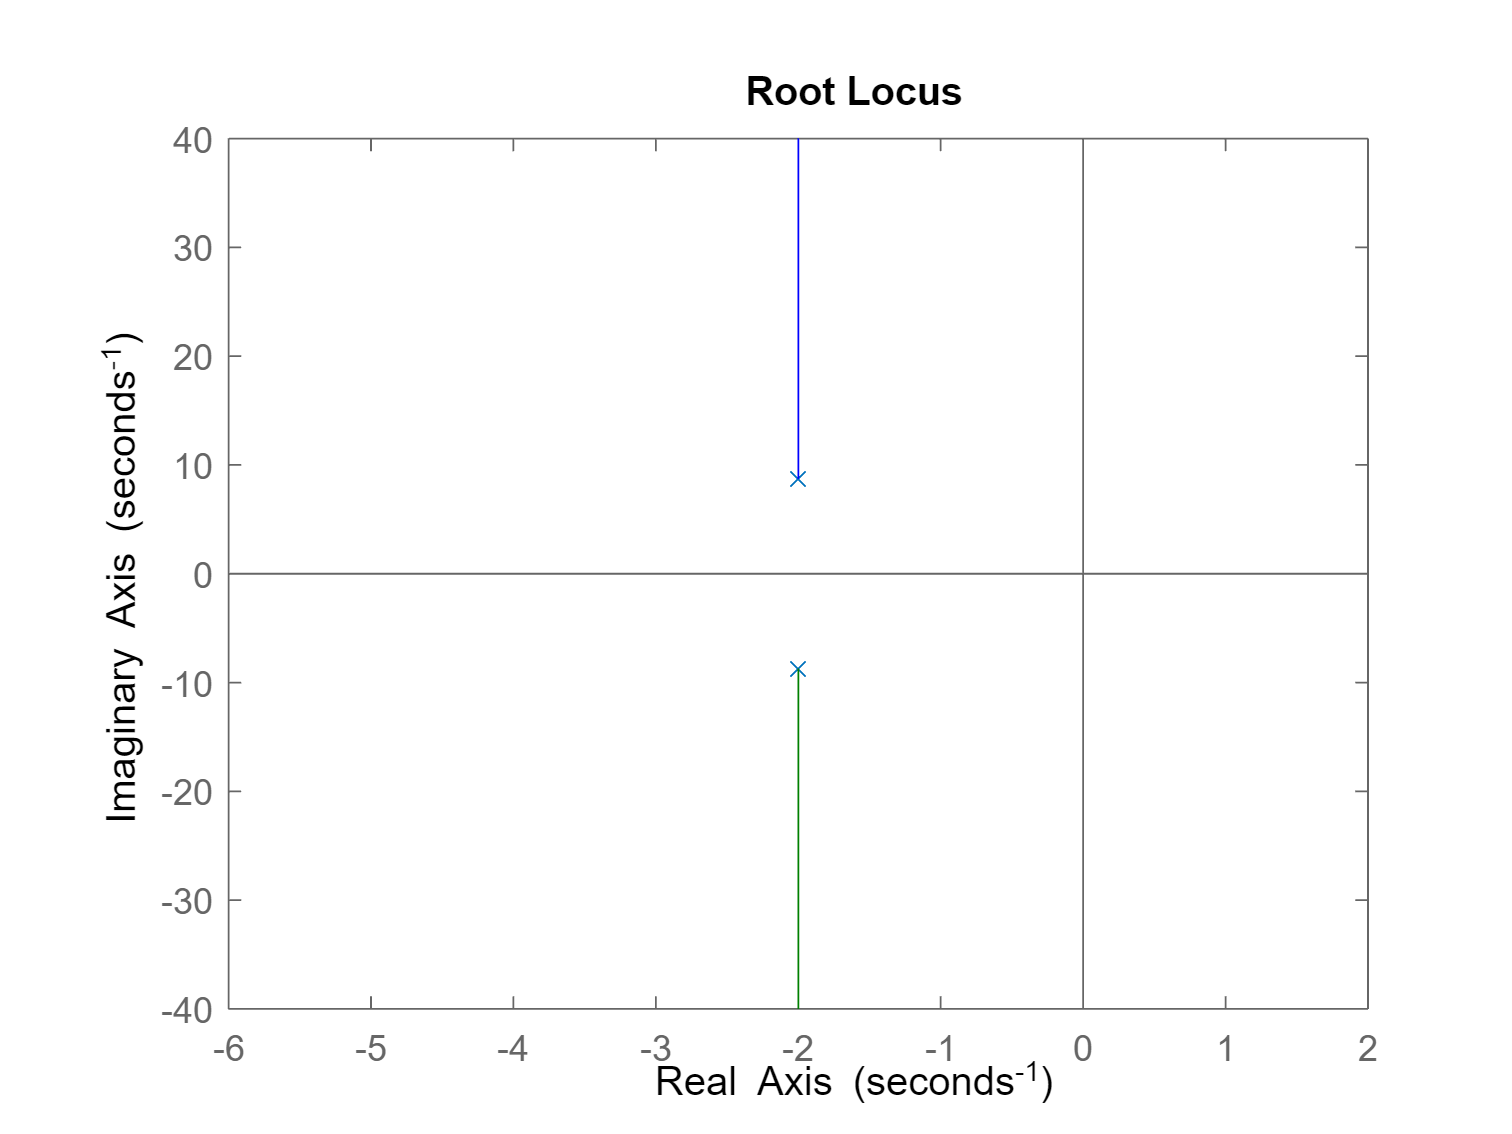

rlocus(T_s_tf)

 What can you say about the stability of the closed loop system what damping ratio’s are achievable using proportional feedback control $D(s) = K$?

What values of % overshoot are achievable using proportional feedback control $D(s) = K$?

**2. Stability and Controller Design** (30 marks)

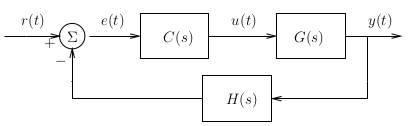

Consider the system shown above where:

 $C(s)=K$, $G(s)=\frac{1}{s(s+2)}$, and $H(s)=\frac{10}{s+10}$. 

a) (5 marks) Use Matlab's symbolic computing to compute the closed loop transfer function of the system. Assign the computed closed loop transfer function the variable $\texttt{G_cl_symQ2a}$.

% You code goes here

syms K s

C_s = K;
G_s = 1/(s*(s+2));
H_s = 10/(s+10);

T_s = (C_s*G_s)/(1+C_s*G_s*H_s);
G_cl_symQ2a=collect(T_s)

$$G\_cl\_symQ2a = \frac{K\,s+10\,K}{s^{3}+12\,s^{2}+20\,s+10\,K}$$

b) (5 marks) For what values of K is the closed loop system stable? Justify your answer using matlab and explanation.

%Your code goes here


syms s K
RT=[s^4 0 12 10*K;s^3 1 20 0];
RT=[RT;s^2 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) -det([RT(1,2) RT(1,4);RT(2,2) RT(2,4)])/RT(2,2) 0];
RT=[RT;s^1 -det([RT(2,2) RT(2,3);RT(3,2) RT(3,3)])/RT(3,2) -det([RT(2,2) RT(2,4);RT(3,2) RT(3,4)])/RT(3,2) 0];
RT=[RT;s^0 -det([RT(3,2) RT(3,3);RT(4,2) RT(4,3)])/RT(4,2) -det([RT(3,2) RT(3,4);RT(4,2) RT(4,4)])/RT(4,2) 0]

$$RT = \left(\begin{array}{cccc} s^{4} & 0 & 12 & 10\,K\\ s^{3} & 1 & 20 & 0\\ s^{2} & 12 & 10\,K & 0\\ s & 20-\frac{5\,K}{6} & 0 & 0\\ 1 & \frac{25\,K\,\left(K-24\right)}{3\,\left(\frac{5\,K}{6}-20\right)} & 0 & 0 \end{array}\right)$$

s0_entry = simplify(RT(5,2))

$$s0\_entry = 10\,K$$

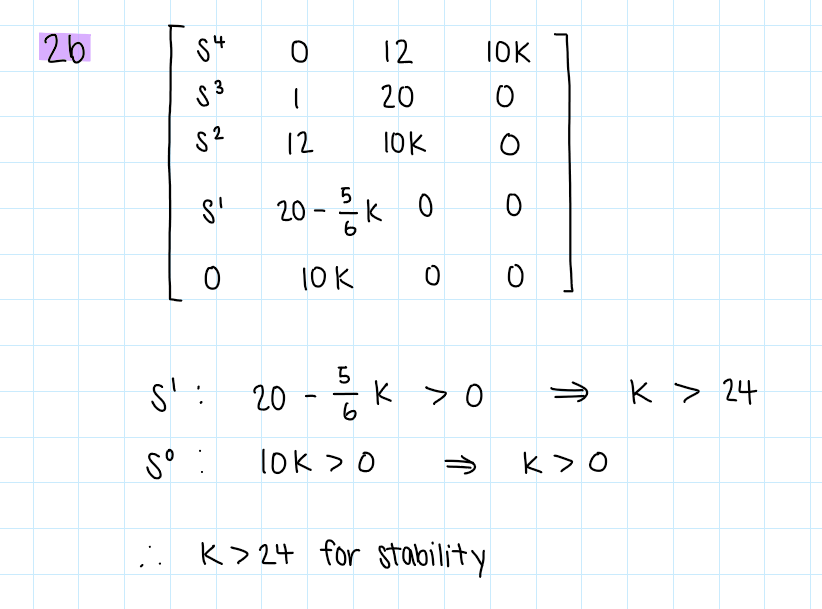

c) (5 marks) For the value of $K$ when the system is marginally stable (i.e. the closed loop system has pole(s) of multiplicity 1 on the $j\omega$-axis and the other closed loop poles are in the open right half plane), calculate the value of the poles on the$j\omega$-axis. Assign the values to the variable $\texttt{omega\_crossingQ1d}$ . 

% Your code goes here
K = 24;

row_above_zeros = 12*s^2+10*K;
omega_crossingQ1d = solve(row_above_zeros, s)

$$omega\_crossingQ1d = \left(\begin{array}{c} -\sqrt{20}\,\mathrm{i}\\ \sqrt{20}\,\mathrm{i} \end{array}\right)$$

d) (5 marks) Suppose you want to change the design of the controller $D(s)$ in the closed loop control system so that the new closed loop system results in a step response with 36.5% overshoot and 3 second settling time. 

Assuming ideal 2nd order behaviour, what would be the new location for the dominant poles? 

**NOTE: **Underdamped poles appear in complex conjugate pairs. Assign to the variable $\texttt{s_dQ2}$ the new desired values of both dominant poles. This should be a two element vector. 

% Your code goes here

OS_new = 0.365;
Tsettling_new = 3;

s = tf('s');
K = 24;

C_s = K;
G_s = 1/(s*(s+2));
H_s = 10/(s+10);

Ts = feedback(C_s*G_s,H_s);
p = pole(Ts)

p =  -12.0000 + 0.0000i
   0.0000 + 4.4721i
   0.0000 - 4.4721i



final_value = evalfr(Ts,0);





%s_dQ2=[ ]

e) (5 marks) Design a PD compensator $D(s)=K\left (s+z_c\right)$ to place the dominant poles at the location you computed in part (3d).

% Your code goes here
% % z_cQ2e= %Variable to assign value of z_c above
% % KQ2e=    %Varible to assign the value of K above

What is the close loop transfer function for your new system?

%Your code goes here
%G_clQ2e=  % Variable for closed loop transfer function

 What is the actual % overshoot of the new closed loop system in response to a step input?

%actualPOS=  %Variable to store the actual % overshoot of G_clQ2e system

Does the closed loop system have the desired % overshoot and settling time (i.e. was the 2nd order approximation valid)?

% Uncomment the correct answer
%Q2e2ndOrderValid=true
%Q2e2ndOrderValid=false

Explain why the closed loop system is or is not a valid 2nd order approximation using text and matlab as needed in the space below

%Your matlab code here


f) (5 marks) Use Matlab to plot the open loop bode plot of $D(s)G(s)H(s)$ for your answer to part (e):

% Your code goes here


What is the gain margin $\texttt{Gm}$ for the system above system? 

% Your code goes here
%Gm=

What is the phase margin $\texttt{Pm}$ for the system above and what is the frequency $\texttt{Wcp}$ at which the phase margin occurs? 

% Your code goes here
%Pm=
%Wcp=

Using the above information, determine the maximum amount of delay that could be added into the system in say, implmenting the controller on a digital computerand getting the control output to the actuators, before the closed loop system would become unstable.

% Your code goes here
%DelayQ2f=


Find the bandwidth of the closed loop system in question (e) using Matlab and asign it to the variable $\texttt{omega\_BM}$:

% Your code here
%omega_BW=

**3. Steady State Error & Disturbance Rejection** (25 marks)

a) (5 marks) Consider the system $G(s)=\frac{2\,s-2}{2\,s^4+29\,s^3+134\,s^2+185\,s}$ with $D(s)=K$ in following closed loop control system:  

Is the following statement true or false:

    You can use the static error constant to predict the steady state error of this system. 

% Uncomment the correct answer
StatementIsCorrectQ3a=true

StatementIsCorrectQ3a = logical
   1


%StatementIsCorrectQ3a=false

Justify your answer with a textual explanation and matlab code as you see fit in the space below

%Your supporting code goes here


% steady state error formula has the static error constant in it

syms s K
D_s = K;
G_s = (2*s-2)/(2*s^4+29*s^3+134*s^2+185*s);
%T_s = (D_s*G_s)/(1+D_s*G_s);
T_s = D_s*G_s

$$T\_s = \frac{K\,\left(2\,s-2\right)}{2\,s^{4}+29\,s^{3}+134\,s^{2}+185\,s}$$

T_s = collect(T_s)

$$T\_s = \frac{\left(2\,K\right)\,s-2\,K}{2\,s^{4}+29\,s^{3}+134\,s^{2}+185\,s}$$


% type 1 system , because s^1 (factor out s) 

b) (5 marks) Now assume that $D(s)=K$ and $G(s)=\frac{s+1}{s^4+\frac{29}{2}\,s^3+\frac{134}{2}\,s^2+\frac{185}{2}\,s}$

in the following control system:

What is the type of the system? Uncomment and set variable $\texttt{n\_type}$ to the type of the system.  

% Your code goes here

syms s K

D_s = K;
G_s = (s+1)/(s^4+(29/2)*s^3+(134/2)*s^2+(185/2)*s);
%T_s = (D_s*G_s)/(1+D_s*G_s);
T_s = D_s*G_s

$$T\_s = \frac{K\,\left(s+1\right)}{s^{4}+\frac{29\,s^{3}}{2}+67\,s^{2}+\frac{185\,s}{2}}$$

T_s = collect(T_s)

$$T\_s = \frac{\left(2\,K\right)\,s+2\,K}{2\,s^{4}+29\,s^{3}+134\,s^{2}+185\,s}$$

n_type= 1

n_type = 1

% type 1 because 1 s can get factored out

Explain your answer in the space below:

What is its static error constant for a given gain $K$? Put your code below to compute the static error constant and uncomment and  assign it to the variable $\texttt{K\_staticError}$. 

**NOTE:** I suggest using the $\texttt{minreal}$matlab command to help you answer this question. Type $\texttt{help minreal}$at the command prompt to understand how this command works.

% Your code goes here

%K_staticError= subs(T_s,s,0)
K_staticError = inf

K_staticError = Inf

 What is the steady state error of the closed loop system in response to a unit step input? Assign your answer the variable $\texttt{e\_stepQ3a}$

% Your code goes here
e_stepQ3a= 1/(1+K_staticError)

e_stepQ3a = 0

 What is the steady state error of the closed loop system in response to a unit ramp input? Assign your answer the variable $\texttt{e\_rampQ3a}$

% Your code goes here
% because 1/Kv, but Kv is 0 in type 0

K_v = limit(G_s*s)

$$K\_v = \frac{2}{185}$$

e_rampQ3a=1/K_v

$$e\_rampQ3a = \frac{185}{2}$$

c) (10 marks) For $G(s)=\frac{s+1}{s^4+\frac{29}{2}\,s^3+\frac{134}{2}\,s^2+\frac{185}{2}\,s}$ design a controller more complex controller $D(s)$ so that the closed loop system is stable and tracks ramps with zero steady state error. Pick a gain value $K$for your controller so that the closed loop system visibly converges to ramp input when you similate the first 5-10 seconds of a ramp input to the system.

**NOTE: **You can use the matlab command $\texttt{impulse(R,G\_clQ3c*R,10)}$to plot the first 10 seconds of the Laplace transform of an input $\texttt{R}$ and the response of a plant model $\texttt{G\_cl}$ to the input $\texttt{R}$.

% Your code to help justify your answer goes here

s = tf('s');
K = 500;
D_Q3c= K;   %assign your controller to this variable
G_s = (s+1)/(s^4+(29/2)*s^3+(134/2)*s^2+(185/2)*s);
T_s= (D_Q3c*G_s)/(1+D_Q3c*G_s); %Compute the closed loop controller for simulation in this
num = [0 0 0 2*K 2*K];
denom = [2 29 134 2*K+185 2*K];
G_clQ3c = tf(num,denom)

G_clQ3c =
 
               1000 s + 1000
  ----------------------------------------
  2 s^4 + 29 s^3 + 134 s^2 + 1185 s + 1000
 
Continuous-time transfer function.



R = 1/s^2   %ramp input is 1/s^2

R =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



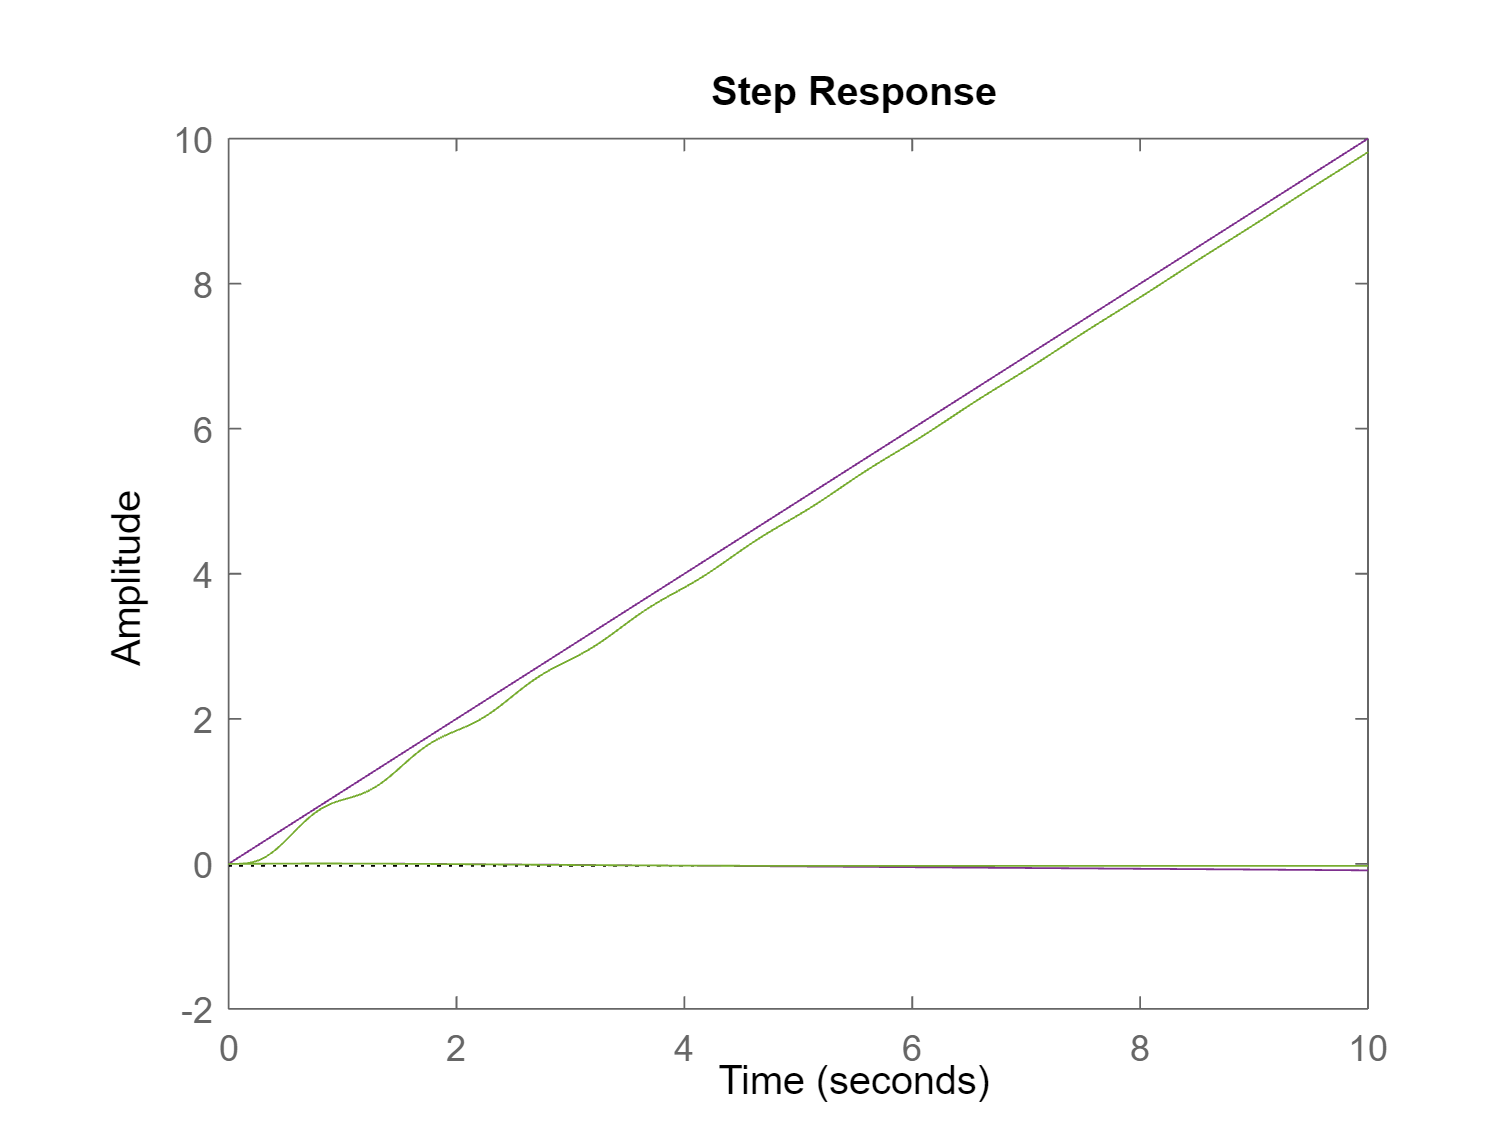

impulse(R,G_clQ3c*R,10)

e) (5 marks) For your controller $D(s)$ that you designed in the previous part of this question and the plant $G(s)=\frac{s+1}{s^4+\frac{29}{2}\,s^3+\frac{134}{2}\,s^2+\frac{185}{2}\,s}$, suppose there is a step disturbance at input $D_i(s)$ as shown below:

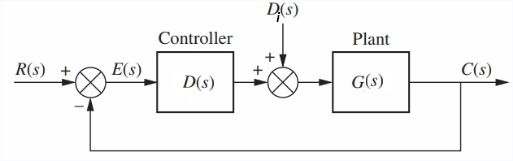

What is the steady state error resulting from a unit step disturbance at input $D_i(s)$?

%Your code goes here

syms s
R_s = 1/s^2;     % same as above
Di_s = 1/s;   % unit step disturbance

D_s = 500;
G_s = (s+1)/(s^4+(29/2)*s^3+(134/2)*s^2+(185/2)*s);

% eR = (s/(1+D_s*G_s))*R_s;   we already solved for eR above, don't need
eD = -((s*G_s)/(1+D_s*G_s))*Di_s;


%e =eR+eD;
eD = collect(eD)

$$eD = \frac{-2\,s-2}{2\,s^{4}+29\,s^{3}+134\,s^{2}+1185\,s+1000}$$

e_ssQ3e = subs(eD,s,0)

$$e\_ssQ3e = -\frac{1}{500}$$

**4. State Space Control** (25 marks)

Assume that the transfer function  of a plant (system you want to control) is given by:


$$G(s)=\frac{s^2+6\,s-7}{s^5+\frac{43}{2}\,s^4+\frac{337}{2}\,s^3+\frac{1123}{2}\,s^2+\frac{1295}{2}\,s}$$


a) (5 marks) Given G(s) what is the controller canonical (phase variable) state space representation of the plant G(s)? Uncomment and assign your answers to the variables below:

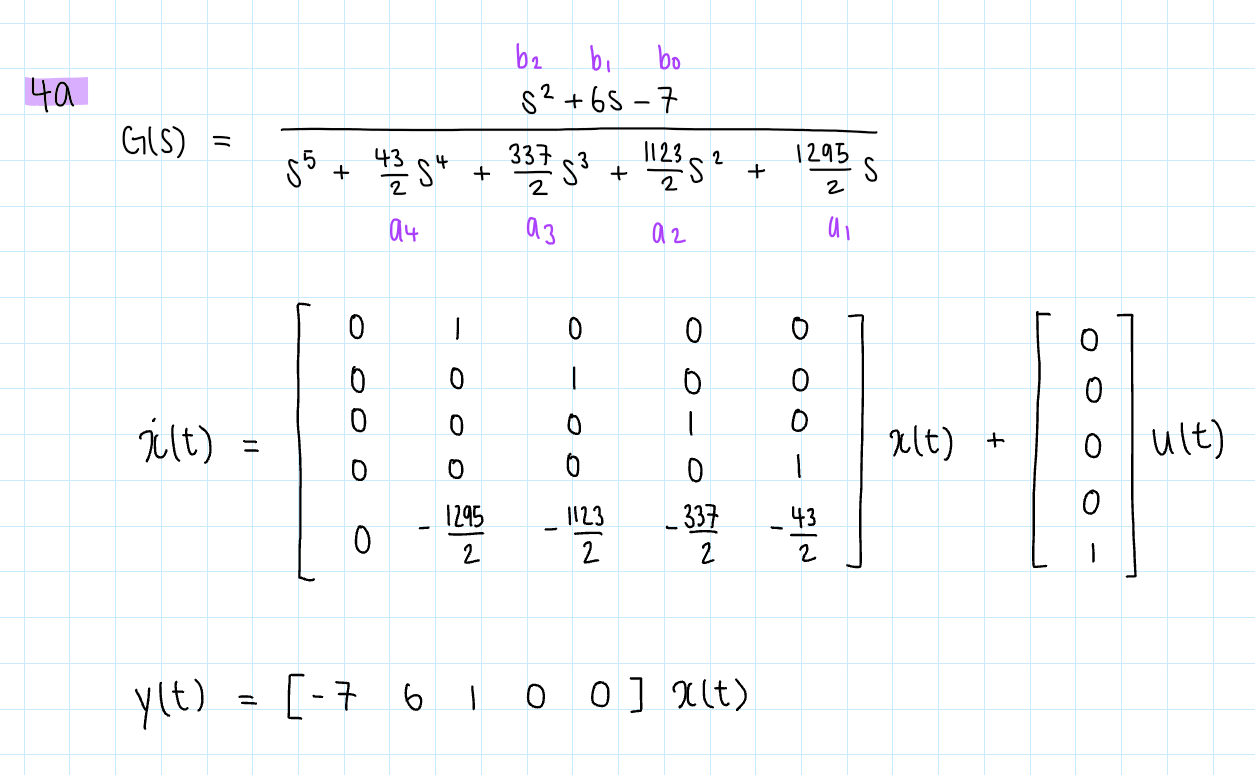

% Your code goes here
A_identity = zeros(5,5);
A_identity(1:4,2:5) = eye(4);
A_identity(5,1:5) = [0 -1295/2 -1123/2 -337/2 -43/2];
A = A_identity

A =          0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000
         0 -647.5000 -561.5000 -168.5000  -21.5000


B = [0;0;0;0;1]

B =      0
     0
     0
     0
     1


C = [-7 6 1 0 0]

C =     -7     6     1     0     0


D = 0

D = 0

Verify that your state space representation is controllable using matlab commands:

%Your code goes here

G_s = tf([0 0 0 1 6 -7], [1 43/2 337/2 1123/2 1295/2]);



 

b) (5 marks) A state feedback control $u = -Kx$ is to be used to:

• place one of the closed loop poles is to be placed at $s = -7$ to exactly cancel one of the system zeros,

• place the dominant poles at $s = -0.5 \pm j0.6$ to get a desired % overshoot and settling time, and

• place the final two poles at $s = -5\pm j6$ so that they should not interfere with the dominant poles.

What would the desired characteristic equation of the designed closed loop system be? 

Create a symbolic polynomial in $s$ and assign it to the variable $\texttt{d_desiredQ4}$

% Your code goes here


d_desiredQ4 = (s-(-0.5+j*0.6))*(s-(-0.5-j*0.6))*(s-(-5+j*6))*(s-(-5-j*6))*(s+7)

d_desiredQ4 =
 
  s^5 + 18 s^4 + 148.6 s^3 + (568.4+3.553e-15i) s^2 + (506.9+2.132e-14i) s + (260.5-2.487e-14i)
 
Continuous-time transfer function.



c) (5 marks) Use Matlab to compute a state feedback control matrix $K$ to place the poles at the desired locations. Assign your answer to the variable $\texttt{K\_Q4c}$

% Your code goes here

G_s_num = [0 0 0 1 6 -7];
G_s_denom = [1 43/2 337/2 1123/2 1295/2];


sys = ss(A,B,C,D);
poles = pole(sys)

poles =    0.0000 + 0.0000i
  -7.0000 + 0.0000i
  -6.0000 + 1.0000i
  -6.0000 - 1.0000i
  -2.5000 + 0.0000i


% figure(1);
% step(sys);
% hold on
p = [-0.5+j*0.6, -0.5-j*0.6, -5+j*6, -5-j*6, -7];

K_Q4c=place(A,B,p)

K_Q4c =   260.4700 -140.5900    6.8700  -19.8900   -3.5000


% Acl = A-B*K;
% syscl = ss(Acl,B,C,D);
% Pcl = pole(syscl);
% figure(1);
% step(syscl);


d) (5 marks) Is the state space representation from part (4a) observable so that we can implement our state feedback controller given our current sensor outputs? Justify your answer with the help of Matlab the assign the correct truth value to the variable $\texttt{Q4aObservable}$ below.

% Your code goes here
%





%
% Uncomment the correct answer
%Q4aOservable=true
%Q4aOservable=false

e) (5 marks) If a state space system is either unobservable, uncontrollable, or both when it is taken from a transfer function, then it is because there was actually at least one pole/zero cancellation that could have been made in the transfer function to reduce the order of the transfer function before construction of the state space representation. In our case we started from the transfer function:


$$G(s)=\frac{s^2+6\,s-7}{s^5+\frac{43}{2}\,s^4+\frac{337}{2}\,s^3+\frac{1123}{2}\,s^2+\frac{1295}{2}\,s}$$


Use matlab to compute the poles and zeros of the transfer function

%polesQ4d=
%zerosQ4d=

Cancel the common pole and zero and give the new "minimal" transfer function: 

%G_minQ4d=

Give the state space representation of this new transfer function and verify that the state space representation is both controllable and observable.

%A_min=
%B_min=
%C_min=
%D_min=
